# **Ejercicio 2**

## Problema T5.2 Método de interpolacion de Neville

Limpieza del entorno de trabajo

clear, clc 

a) Escribe una función de Matlab que calcule el punto de

interpolación mediante el método de Neville. Nombra a la función:

`yint = Neville(x,y,xint) `donde:

`x,y` son los vectores con los puntos de datos

`xint `el punto donde se quiere interpolar

`yint` el valor de interpolación obtenido

- Véase Neville.m

b) Emplea la función del apartado a) para encontrar la raíz 𝑦(𝑥) = 0. Comprueba el

resultado con las raíces del polinomio de interpolación de segundo grado 

calculado con la función polyfit de Matlab.Representa los puntos y 

la función de interpolación con el fin de verificar la posición 

de la raíz encontrada.

Datos de la tabla

x = [4.0; 3.9; 3.8; 3.7];
y = [-0.06604; -0.02724; 0.01282; 0.05383];

Se acomodan los vectores para poder representar gráficamente el polinomio de interpolación, además de buscar la raíz de `y(x)=0`

xx = linspace(min(x),max(x),1000)';
yy = zeros(size(xx))';
for i=1:length(xx)
    yy(i) = Neville(x,y,xx(i));
end

Se encuentra la raíz

indice = find(abs(yy) == min(abs(yy)));

Se imprime la aproximación de la raíz

fprintf('Raíz obtenida por Neville: x = %.4f\n', xx(indice))

Raíz obtenida por Neville: x = 3.8318


Calculamos las raíces del polinomio de interpolación de segundo grado con `polyfit`

p= polyfit(x, y, 2);
raices = roots(p);

 Se imprime las raíces del polinomio de interpolación

fprintf('Raíces del polinomio de interpolación: x = %.4f, x = %.4f\n', raices(1), raices(2))

Raíces del polinomio de interpolación: x = 11.1022, x = 3.8317


Se representan los puntos y la función de interpolación

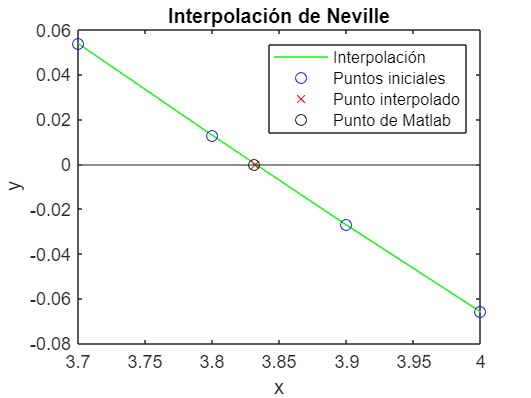

xlim([min(x), max(x)]);
plot(x,y,"g-",x,y,"bo",xx(indice),yy(indice),"rx",raices(2),0,'ko');
title('Interpolación de Neville');
xlabel("x");
ylabel("y");
yline(0);
legend("Interpolación","Puntos iniciales","Punto interpolado","Punto de Matlab","Location","northeast");